clc
clear
close all

disp('TRANSFER FUNCTION TO SIGNAL FLOW GRAPH AND BACK')

TRANSFER FUNCTION TO SIGNAL FLOW GRAPH AND BACK



%% --------------------------------------------------
% STEP 1 : Define Transfer Function
%% --------------------------------------------------

num = [1];
den = [1 3 2];

G = tf(num,den);

disp('Original Transfer Function:')

Original Transfer Function:


G


G =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



%% --------------------------------------------------
% STEP 2 : Convert Transfer Function to State Space
%% --------------------------------------------------

[A,B,C,D] = tf2ss(num,den);

disp('State Space Representation')

State Space Representation


disp('Matrix A =')

Matrix A =


disp(A)

    -3    -2
     1     0




disp('Matrix B =')

Matrix B =


disp(B)

     1
     0




disp('Matrix C =')

Matrix C =


disp(C)

     0     1




disp('Matrix D =')

Matrix D =


disp(D)

     0



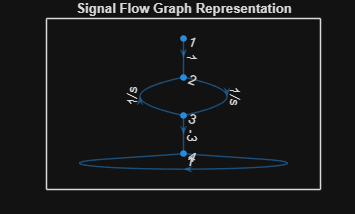


%% --------------------------------------------------
% STEP 3 : Construct Signal Flow Graph
%% --------------------------------------------------

nodes = {'R','X1','X2','Y'};

s = [1 2 3 3 4];
t = [2 3 4 2 4];

gain = {'1','1/s','1/s','-3','1'};

Ggraph = digraph(s,t);

figure
plot(Ggraph,'Layout','layered','EdgeLabel',gain)
title('Signal Flow Graph Representation')


%% --------------------------------------------------
% STEP 4 : Mason Gain Formula Calculation
%% --------------------------------------------------

% Define symbolic gains
syms G1 G2 H

% Forward path
P1 = G1*G2;

% Loop gain
L1 = -G1*G2*H;

% Delta
Delta = 1 - L1;

% Delta_k (no touching loops)
Delta1 = 1;

% Transfer Function using Mason
T = simplify((P1*Delta1)/Delta);

disp('Transfer Function using Mason Gain Formula:')

Transfer Function using Mason Gain Formula:


disp(T)

$$\frac{G_{1}\,G_{2}}{G_{1}\,G_{2}\,H+1}$$


%% --------------------------------------------------
% STEP 5 : MATLAB Closed Loop Verification
%% --------------------------------------------------

G1_tf = tf([1],[1 1]);
G2_tf = tf([1],[1 2]);
H_tf  = tf([1],[1]);

forward_path = series(G1_tf,G2_tf);

T_closed = feedback(forward_path,H_tf);

disp('Closed Loop Transfer Function using MATLAB:')

Closed Loop Transfer Function using MATLAB:


T_closed


T_closed =
 
        1
  -------------
  s^2 + 3 s + 3
 
Continuous-time transfer function.


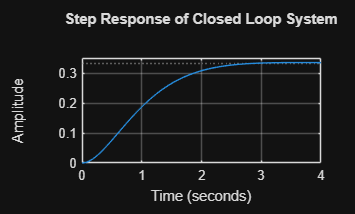


%% --------------------------------------------------
% STEP 6 : Step Response
%% --------------------------------------------------

figure
step(T_closed)
grid on
title('Step Response of Closed Loop System')

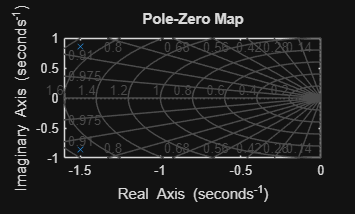


%% --------------------------------------------------
% STEP 7 : Pole Zero Plot
%% --------------------------------------------------

figure
pzmap(T_closed)
grid on
title('Pole-Zero Map')

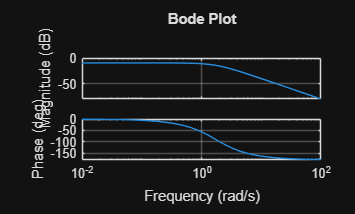


%% --------------------------------------------------
% STEP 8 : Bode Plot
%% --------------------------------------------------

figure
bode(T_closed)
grid on
title('Bode Plot')


disp('Program Completed Successfully')

Program Completed Successfully
